**Final Project: Lee wave equation - PDE evaluation**

Equations:

Lee wave PDE

w = omega, vertical velocity

 

where *l *is the scorer parameter... 

Definition of variables: 

N = buoyancy frequency

U = mean flow

k = horizontal wavenumber

m =vertical wavenumber

 = condition for vertical propogation

h = topography (the surface)

Boundary conditions (?):

z = h(x)

h(x) = h_0* sin(kx)

w(x,0) = U*h_0*k*cos(kx)

substituting BC in gives us this....

z-> infinity (bc the atmosphere has no upper boundary) - would be need to pick a value in order for our model to work??

use values from here:

[https://a.atmos.washington.edu/academics/classes/2010Q1/536/2003AP_lee_waves.pdf](https://a.atmos.washington.edu/academics/classes/2010Q1/536/2003AP_lee_waves.pdf) 

N = 0.01s^-1

U = 15ms^-1

use finite differencing to solve this BVP

*Dirichlet boundary conditions 

dirichlet - at the top of z for perturbation energy

if k>l

where mu = -v^0.5  and v = (l^2 - k^2)^0.5

if k<l

where v = (l^2 - k^2)^0.5  ---> can't use mu here because parts would be imaginary because k<l

## Analytical Solution

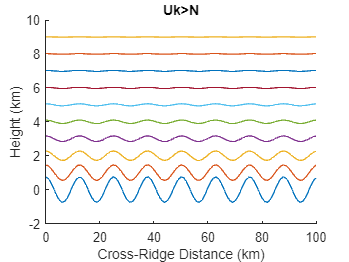

k = 0.5; %horizontal wave number -> larger the wavelength, smaller k (bc by definition its wavelengths per unit distance)
U = 15; %m/s
N = 0.01; %s^-1
l = sqrt(N^2/U^2);
mu = sqrt(k^2 - l^2);
% initialize x - cross ridge distance
xf = 100; %km
xi = 0; 
dx = 1;
x = xi:dx:xf;
zf = 9; %9km
z0 = 0;
dz = 1; 
z = z0:dz:zf;
h0 = 0.1;
%vertical velocity 
w = zeros(length(z),length(x));
%calculate all of w

for i = 1:length(z)
    for j = 1:length(x)
        w(i,j) = (U * h0 * k * cos(k*x(j))*exp(-mu*z(i)))+z(i);
        %rows = each level of Z
        %columns = each x value 
    end 
end 
%plot row by row (by height)
figure()
xlabel('Cross-Ridge Distance (km)');
ylabel('Height (km)');
title('Uk>N');
for g = 1:10
    hold on;
    plot(x,w(g,:))
end
hold off;

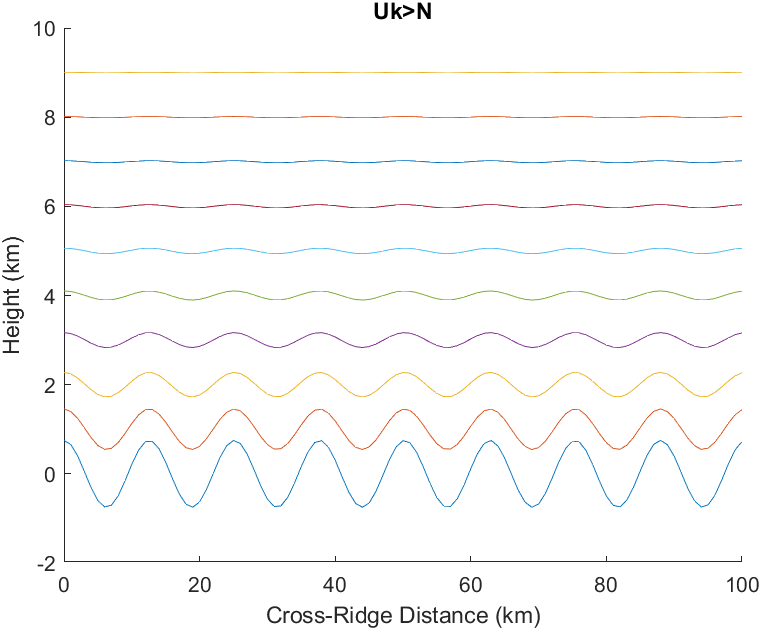

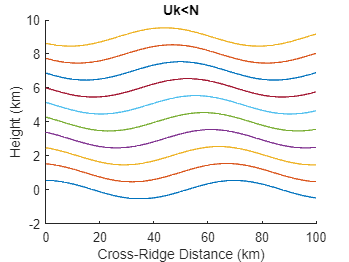

clear
%change so that Uk < N 
U = 15;
N = 0.01;
k = 0.0009;
l = sqrt(N^2/U^2);
v = sqrt(l - k^2);
xf = 100; %km
xi = 0; 
dx = 1;
x2 = xi:dx:xf;
zf = 9; %9km
z0 = 0;
dz = 1; 
z2 = z0:dz:zf;
h0 = 40;
%vertical velocity 
w2 = zeros(length(z2),length(x2));
%calculate all of w

for i = 1:length(z2)
    for j = 1:length(x2)
        w2(i,j) = (U * h0 * k * cos(k*x2(j)*100 + v*z2(i)*10))+z2(i);
        %rows = each level of Z
        %columns = each x value 
    end 
end 
%plot row by row (by height)
figure()
xlabel('Cross-Ridge Distance (km)');
ylabel('Height (km)');
title('Uk<N');
for c = 1:10
    hold on;
    plot(x2,w2(c,:))
end
hold off;

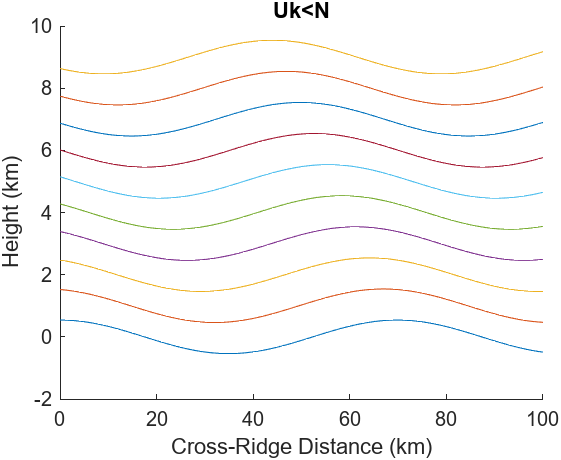

Solving PDE: Crank-Nelson Method

dx=1;
xf = 100;
x = 0:dx:xf;


%use Crank Nelson method!!
D = 0.1;
dz = 1; %meters
dx = 1; %days
zf = 9; %meters
n = zf/dz;
z = 0:dz:zf;
%diffusion number - from notes:C_d = D*dx / dz^2
C_d = (D*dx)/(dz^2);
%C_d = 1
%create R & L Matrices

dataL = [-0.5*C_d*ones(n,1), (1+1*C_d)*ones(n,1), -0.5*C_d*ones(n,1)];
diag = [-1, 0, 1];
L = spdiags(dataL , diag,n-2,n-2);
L = full(L);
dataR = [0.5*C_d*ones(n,1), (1-C_d)*ones(n,1), 0.5*C_d*ones(n,1)];
R = spdiags(dataR, diag,n-2,n-2);
R = full(R);
% from class: J_k+1 = R * J_k \ L


%w(i,j) = (U * h0 * k * cos(k*x(j))*exp(-mu*z(i)))+z(i);
% x ranges from 0 to 100 km
% z ranges from 0 to 9 km 


%need to make a nested for loop to run through both z and x


%create matrix for surface boundary condition
% w(x,0) = U*h_0*k*cos(kx)
h0= 0.1

h0 = 0.1000

k = 0.5

k = 0.5000

U = 15

U = 15

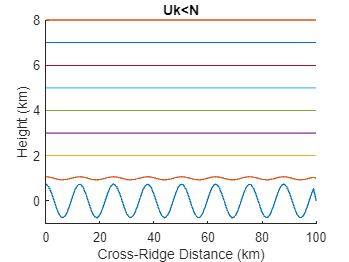


surfaceM = zeros(length(x),1);
for i = 1:dx:xf
    surfaceM(i,1) = (U * h0 * k * cos(k*x(i)))+z(1);
end
% create matrix for upper boundary condition - assume perturbation energy
% goes to zero (not sure this is an ok assumption)
topM = zeros(1, length(x));

middleM = zeros(n-2,length(x));


W = zeros(n-2,length(x));
W(1,:) = surfaceM;
W(end,:) = topM;

%loop through and create the numerically solving matrix values

for k = 1:length(x)
    middleM(:,k) = inv(L)* ((R*middleM(:,k)) + 0.5*C_d*W(:,k) + 0.5*C_d*W(:,k));
end

finalM = zeros(n,length(x));
finalM(1,:) = surfaceM;
finalM(2:end-1, :) = middleM;
finalM(end,:) = topM;

for e = 1:zf
    finalM(e,:) = finalM(e,:) + z(e);
end


figure()
xlabel('Cross-Ridge Distance (km)');
ylabel('Height (km)');
title('Uk<N');
for c = 1:9
    hold on;
    plot(x,finalM(c,:))
end
hold off;

%need to factor in height changes, somewhere we need to add a km each
%height
% 
% figure()
% plot(x(99:end), finalM(:,99:end))